# Question 3 (18 Marks)

In this question, your task is to find the solution of the following differential equation:


$$\overset{\ldotp }{x} =\textrm{Ax}\left(t\right)$$


With the matrix A stored in Q3data.mat, with initial condition (also stored in Q3data):


$$x\left(0\right)=X_0$$


Note that one way to solve this particular problem is using matlab's matrix exponential function expm as follows:

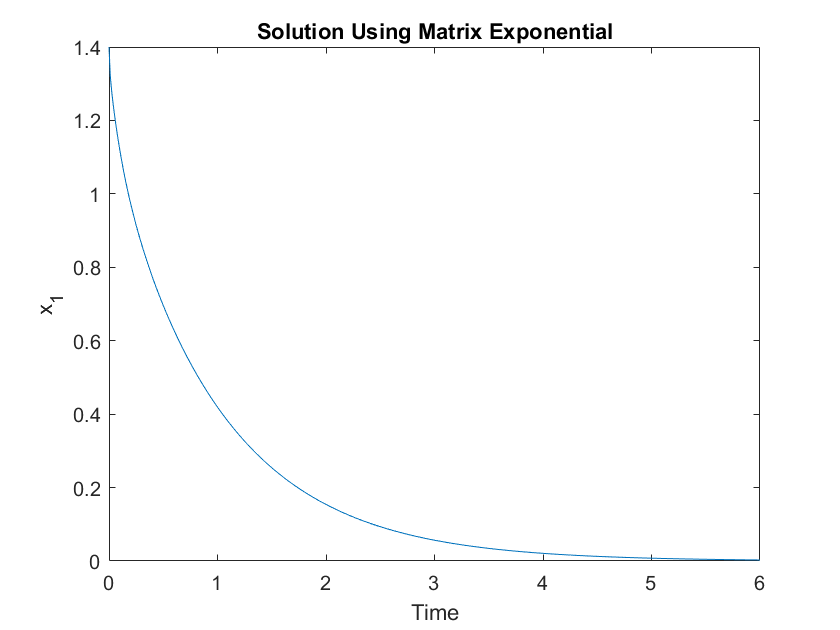

clear all
clf

load Q3data %load the matrix A and initial condition X0

tpoints = linspace(0,6,500);
for I = 1:length(tpoints)
    x(:,I) = expm(A*tpoints(I))*X0;
end

% Plot the first entry of the x vector
plot(tpoints,x(1,:))
xlabel('Time')
ylabel('x_1')
title('Solution Using Matrix Exponential')

**Part 1 (5 Marks)**

In lecture 17 we saw that one application of eigenvalues and eigen vectors is find the the solution of systems similar to the one we have in this questions. Use this approach in order to find the solution and plot the first entry of the x vector as a function of time from 0 to six seconds (similar to the example plot above). Use at least 500 time points in order to get smooth plot. You may use the matlab function eig in order to compute the eigenvalues and eigenvectors.

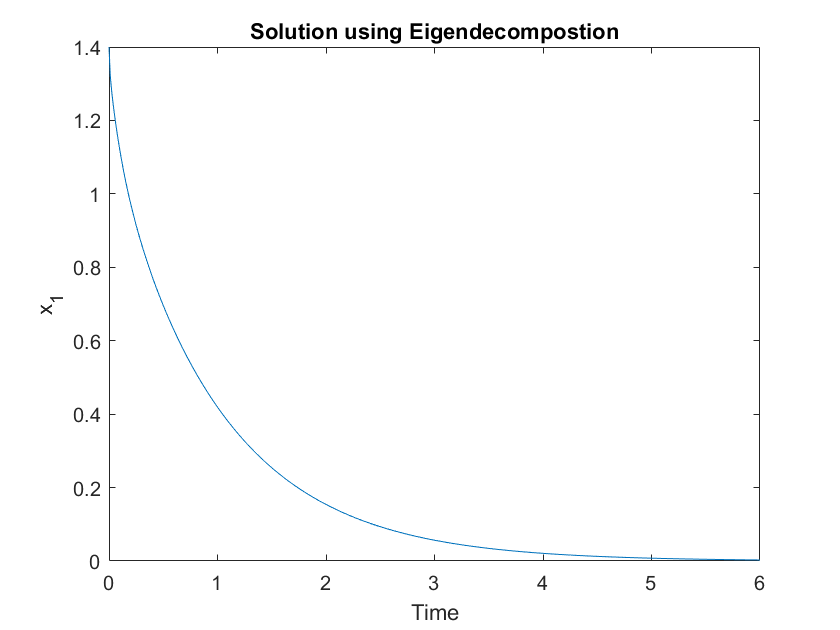

clear all

clf

load Q3data %load the matrix A and initial condition X0


% Your code to compute x goes here. 
% Store the time points the variable tpointseg, and the all the values
% of the x vector in the variable xeg (similar to the code above)
% the lines of code below will plot the graph for you.
tpointseg = linspace(0,6,500);
[V,D]=eig(A);
M=V\X0;
for i=1:length(tpointseg)
    x=0;
    for j=1:5
        x=x+M(j)*V(1,j)*exp(D(j,j)*tpointseg(i));
    end
    xeg(:,i)=x;
end

% Plot the first entry of the x vector
plot(tpointseg,xeg(1,:))
xlabel('Time')
ylabel('x_1')
title('Solution using Eigendecompostion')

**Part 2 (5 Marks)**

Another approach for numerically finding the solution is to use the Backward Eurler (BE) integration formula step in time. Use B.E with at least 500 timepoints to find the solution between 0 and 6 seconds. 

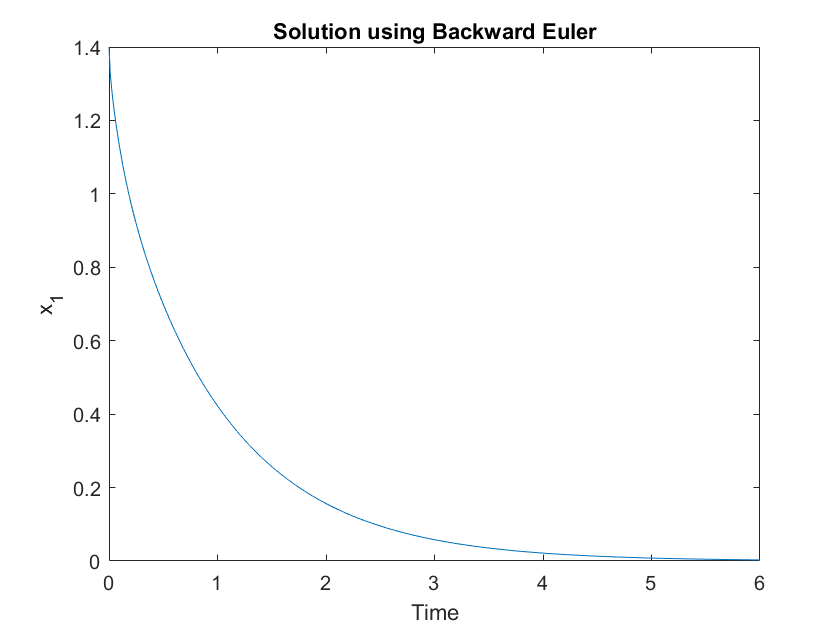

clear all

clf

load Q3data %load the matrix A and initial condition X0

% Your code to compute x goes here. 
% Store the time points the variable tpointsbe, and the all the values
% of the x vector in the variable xbe (similar to the code above)
% the lines of code below will plot the graph for you.
tpointsfe = linspace(0,6,500);
xfe(:,1)=X0;
deltat=6/500;
for i=1:length(tpointsfe)-1
    xfe(:,i+1)=(eye(length(A))-deltat*A)\xfe(:,i);
end

% Plot the first entry of the x vector
plot(tpointsfe,xfe(1,:))
xlabel('Time')
ylabel('x_1')
title('Solution using Backward Euler');

**Part 3 (5 Marks)**

In this part we will repeat Part 2, but this time we will use Forward Euler (FE). Use F.E with at least 500 time points to find the solution between 0 and 6 seconds. 

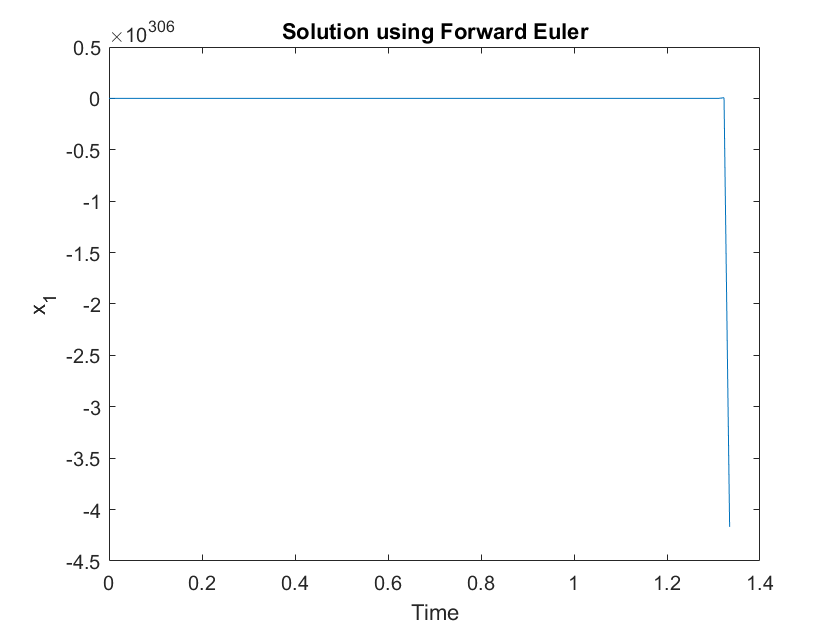

clear all

clf

load Q3data %load the matrix A and initial condition X0

% Your code to compute x goes here. 
% Store the time points the variable tpointsfe, and the all the values
% of the x vector in the variable xfe (similar to the code above)
% the lines of code below will plot the graph for you.
tpointsfe = linspace(0,6,500);
xfe(:,1)=X0;
deltat=6/500;
for i=1:length(tpointsfe)-1
    xfe(:,i+1)=(eye(length(A))+deltat*A)*xfe(:,i);
end

% Plot the first entry of the x vector
plot(tpointsfe,xfe(1,:))
xlabel('Time')
ylabel('x_1')
title('Solution using Forward Euler')

**Part 4 (3 Points)**

Comment on the results of B.E and F.E in parts 2 and 3 above. Which one would you use for this example and why? 

We would use backward euler method since it works perfectly as the matrix exponential and eigendecomposition do. We can see that x_1 is exceptionally high for F.E and it shows the failure of F.E. Forward euler method is unstable and does not always work. Sometimes, it is possible to make forward euler work by making the step smaller, but generally, backward euler is better than forward euler given the same step in terms of stability.